% Moment based kalman filter
clear
close all
rng('default')

% % % % % % % % % % % % % % % % % % % % % % % % % % % %
% ファイル実行場所により下記をコメントアウトする．
% prjファイルを実行した場合は，prjを開いたときに
% 必要なファイルがパスに追加されるのでコメントのままでよい．
% % % % % % % % % % % % % % % % % % % % % % % % % % % %

% addpath("../")
% addpath("../disturbMoment/")

datasetFolder="MRCLAM_Dataset1";
robotNumber = "Robot1";

% true data
% モーションキャプチャで取得した座標を真値とする
groundTruthRaw = importdata(strcat(datasetFolder,"/",robotNumber,"_Groundtruth.dat"));
groundTruth=array2timetable(groundTruthRaw.data(:,2:end), ...
    "RowTimes",seconds(groundTruthRaw.data(:,1)), ...
    "VariableNames",{'trueX','trueY','trueTh'});

% odometry data
odomRaw = importdata(strcat(datasetFolder,"/",robotNumber,"_Odometry.dat"));
odom = array2timetable(odomRaw.data(:,2:3), ...
    "RowTimes",seconds(odomRaw.data(:,1)), ...
    "VariableNames",{'vel','angVel'});

% measurement data
measurementRaw = importdata(strcat(datasetFolder,"/",robotNumber,"_Measurement.dat"));
measurement = array2timetable(measurementRaw.data(:,2:4), ...
    "RowTimes",seconds(measurementRaw.data(:,1)), ...
    "VariableNames",{'barcode','range','bearing'});
landmark_groundTruth = importdata(strcat(datasetFolder,"/","Landmark_Groundtruth.dat"));
landmark_groundTruth = array2table(landmark_groundTruth.data,"VariableNames",{'pole','poleX','poleY','x_std','y_std'});
barcode = readtable(strcat(datasetFolder,"/","Barcodes.dat"));
barcode = renamevars(barcode,[1,2],{'pole','barcode'});
% poleのバーコードの対応が間違えているので修正
barcode.pole(11) = 17;
barcode.pole(17) = 11;
% measurementのデータにbarcodeとlandmarkの座標を対応させる
measurement = innerjoin(measurement,barcode);
measurement = innerjoin(measurement,landmark_groundTruth);
measurement = sortrows(measurement);

% すべてのデータを結合
allData = synchronize(groundTruth,measurement,odom,"union",'previous');
allData = rmmissing(allData); %NaNの行を削除
allData.Time = allData.Time-allData.Time(1) %スタート時間を0にする

allData = 177046×13 timetable
      Time      trueX      trueY     trueTh    barcode    range    bearing    pole    poleX      poleY       x_std         y_std        vel     angVel
    ________    ______    _______    ______    _______    _____    _______    ____    ______    _______    __________    __________    _____    ______

    0 秒        3.4276    -3.2233    2.5192      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.017 秒    3.4231    -3.2201    2.5181      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.024 秒    3.4227    -3.2196    2.5185      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.033 秒    3.4227    -3.2196    2.5185      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.076 秒      3.42    -3.2175     2.521      90       2.148     

dt = 0.1;
allData = retime(allData,'regular','previous','TimeStep',seconds(dt))

allData = 14874×13 timetable
     Time     trueX      trueY     trueTh    barcode    range    bearing    pole    poleX      poleY       x_std         y_std        vel     angVel
    ______    ______    _______    ______    _______    _____    _______    ____    ______    _______    __________    __________    _____    ______

    0 秒      3.4276    -3.2233    2.5192      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.1 秒      3.42    -3.2175     2.521      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.2 秒    3.4158    -3.2153    2.5179      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.3 秒    3.4061    -3.2093     2.518      90       2.148     0.025      16     1.6984    -2.0897    0.00012742    0.00014707    0.067      0   
    0.4 秒    3.4044    -3.2061    2.5243      90       2.148     0.025      16  

% ノイズの設定
noisepattern = 'Gaussian'; %Gaussian or non-Gaussian
% 観測値をログデータから計算する．
if strcmp(noisepattern,'Gaussian')
    rnoize = normrnd(1,0.01,[size(allData,1),1]); %観測値rのノイズ
    phinoize = normrnd(0,0.0007,[size(allData,1),1]); %観測値φのノイズ
elseif strcmp(noisepattern,'non-Gaussian')
    disp('non-Gaussian')
    rnoize = random('Exponential',1/1,[size(allData,1),1]); %観測値rのノイズ
    phinoize = random('Uniform',-pi/12,pi/12,[size(allData,1),1]); %観測値φのノイズ    
end

tx = allData.trueX; %モーションキャプチャで取得したx座標
ty = allData.trueY; %モーションキャプチャで取得したy座標
px = allData.poleX; %参照しているポールのx座標
py = allData.poleY; %参照しているポールのy座標
phi = atan2(py-ty,px-tx)-(allData.trueTh) + phinoize;%観測値φの計算(式16)＋ノイズ
phi = unwrap(phi); %角度が2pi以上変化したものを平行移動する
r = sqrt((tx-px).^2+(ty-py).^2) .* rnoize;%観測値r＋ノイズ

steps = 5000; %計算ステップ

result = zeros(steps,3); %計算結果の格納

% 初期値の設定(allDataの1個目)
x = [allData.trueX(1);allData.trueY(1);allData.trueTh(1)];
sigma_x = [0.01^2,0,0;0,0.01^2,0;0,0,0.01^2];
result(1,:) = x';

for i=2:steps
    % オドメトリ―の速度と角速度にノイズを追加して確率変数とする
    %     ノイズの分布はeq.21
    v = GaussianTPM(allData.vel(i-1),0.01);
    u = GaussianTPM(allData.angVel(i-1),1.0);
    % Step1
    x_app = GaussianMixedTPM3d(x,sigma_x);
    % Step2
    %Step2
    %eq11,eq15
    x_p = zeros(3,1);
    x_p(1) = x_app.X + v.X*x_app.C*dt;
    x_p(2) = x_app.Y + v.X*x_app.S*dt;
    x_p(3) = x_app.Th + u.X*dt;
    %eq11
    sigma_p = zeros(3,3);
    sigma_p(1,1) = x_app.XX + 2*v.X*dt*x_app.XC + v.XX*dt^2*x_app.CC;
    sigma_p(1,2) = x_app.XY+v.X*dt*x_app.XS + v.X*dt*x_app.YC+v.XX*dt^2*x_app.CS;
    sigma_p(1,3) = x_app.XTh + u.X*dt*x_app.X + v.X*dt*x_app.ThC + u.X*v.X*dt^2*x_app.C;
    sigma_p(2,1) = sigma_p(1,2);
    sigma_p(2,2) = x_app.YY + 2*v.X*dt*x_app.YS + v.XX*dt^2*x_app.SS;
    sigma_p(2,3) = x_app.YTh + u.X*dt*x_app.Y + v.X*dt*x_app.ThS + u.X*v.X*dt^2*x_app.S;
    sigma_p(3,1) = sigma_p(1,3);
    sigma_p(3,2) = sigma_p(2,3);
    sigma_p(3,3) = x_app.ThTh + 2*u.X*dt*x_app.Th + u.XX*dt^2;

    sigma_p = sigma_p-x_p*x_p';

    %Step3
    % eq12
    x_papp = GaussianMixedTPM3d(x_p,sigma_p);

    %Step4
    % ノイズの設定
    % ノイズパターンにより形を変える 
    if strcmp(noisepattern,'Gaussian')
        vr = GaussianTPM(1.0,0.01);
        vphi = GaussianTPM(0.0,0.0007);
    elseif strcmp(noisepattern,'non-Gaussian')
        vr = ExpotensialTPM(1);
        vphi = UniformTPM(-pi/12,pi/12);
    end


    % calc yhat.
    % eq13
    y = zeros(2,1);
    px = allData.poleX(i);
    py = allData.poleY(i);
    e_ha = px*x_papp.C-x_papp.XC + py*x_papp.S-x_papp.YS;
    e_hb = py*x_papp.C-x_papp.YC - px*x_papp.S+x_papp.XS;
    y(1) = e_ha*vr.X*vphi.C - e_hb*vr.X*vphi.S;
    y(2) = e_hb*vr.X*vphi.C + e_ha*vr.X*vphi.S;

    % calc sigma_yy
    % eq13
    sigma_yy = zeros(2,2);
    e_ha2 =   (px^2*x_papp.CC-2*px*x_papp.XCC+x_papp.XXCC)...
        + (py^2*x_papp.SS-2*py*x_papp.YSS+x_papp.YYSS)...
        + 2*(px*py*x_papp.CS-px*x_papp.YCS-py*x_papp.XCS+x_papp.XYCS);
    e_hb2 =   (px^2*x_papp.SS-2*px*x_papp.XSS+x_papp.XXSS)...
        + (py^2*x_papp.CC-2*py*x_papp.YCC+x_papp.YYCC)...
        - 2*(px*py*x_papp.CS-px*x_papp.YCS-py*x_papp.XCS+x_papp.XYCS);
    e_hahb =  (px*py*x_papp.CC-px*x_papp.YCC-py*x_papp.XCC+x_papp.XYCC)...
        - (px^2*x_papp.CS-2*px*x_papp.XCS+x_papp.XXCS)...
        + (py^2*x_papp.CS-2*py*x_papp.YCS+x_papp.YYCS)...
        - (px*py*x_papp.SS-px*x_papp.YSS-py*x_papp.XSS+x_papp.XYSS);
    sigma_yy(1,1) = e_ha2*vr.XX*vphi.CC - 2*e_hahb*vr.XX*vphi.CS + e_hb2*vr.XX*vphi.SS;
    sigma_yy(2,2) = e_hb2*vr.XX*vphi.CC + 2*e_hahb*vr.XX*vphi.CS + e_ha2*vr.XX*vphi.SS;
    sigma_yy(1,2)=  e_hahb*vr.XX*vphi.CC + e_ha2*vr.XX*vphi.CS - e_hb2*vr.XX*vphi.CS - e_hahb*vr.XX*vphi.SS;
    sigma_yy(2,1) = sigma_yy(1,2);

    sigma_yy = sigma_yy - y*y';

    %Step4 calc Sigma_xy
    % eq14
    sigma_xy = zeros(3,2);
    e_xha =  px*x_papp.XC - x_papp.XXC  + py*x_papp.XS - x_papp.XYS;
    e_xhb =  py*x_papp.XC - x_papp.XYC  - px*x_papp.XS + x_papp.XXS;
    e_yha =  px*x_papp.YC - x_papp.XYC  + py*x_papp.YS - x_papp.YYS;
    e_yhb =  py*x_papp.YC - x_papp.YYC  - px*x_papp.YS + x_papp.XYS;
    e_thha = px*x_papp.ThC -x_papp.XThC + py*x_papp.ThS- x_papp.YThS;
    e_thhb = py*x_papp.ThC -x_papp.YThC - px*x_papp.ThS+ x_papp.XThS;

    sigma_xy(1,1) =  e_xha*vr.X*vphi.C -  e_xhb*vr.X*vphi.S; %x*y1
    sigma_xy(1,2) =  e_xhb*vr.X*vphi.C +  e_xha*vr.X*vphi.S; %x*y2
    sigma_xy(2,1) =  e_yha*vr.X*vphi.C -  e_yhb*vr.X*vphi.S; %y*y1
    sigma_xy(2,2) =  e_yhb*vr.X*vphi.C +  e_yha*vr.X*vphi.S; %y*y2
    sigma_xy(3,1) = e_thha*vr.X*vphi.C - e_thhb*vr.X*vphi.S; %theta*y1
    sigma_xy(3,2) = e_thhb*vr.X*vphi.C + e_thha*vr.X*vphi.S; %theta*y2

    sigma_xy = sigma_xy - x_p*y';

    %calc gain K and x and sigma_x
    % eq14
    K = sigma_xy/(sigma_yy);
    z = [r(i)*cos(phi(i));r(i)*sin(phi(i))];
    x = x_p + K*(z-y);
    sigma_x = sigma_p - K*sigma_yy*K';
    result(i,:) = x';
end


% 比較用にオドメトリのみのデータをとる
deadReconing = zeros(steps,3);
x = [allData.trueX(1);allData.trueY(1);allData.trueTh(1)];
xt = x(1);
yt = x(2);
tht = x(3);
for ii=1:steps
    v = allData.vel(ii);
    u = allData.angVel(ii);
    xt = xt + v*cos(tht)*dt;
    yt = yt + v*sin(tht)*dt;
    tht = tht + u*dt;
    deadReconing(ii,1) = xt;
    deadReconing(ii,2) = yt;
    deadReconing(ii,3) = tht;
end

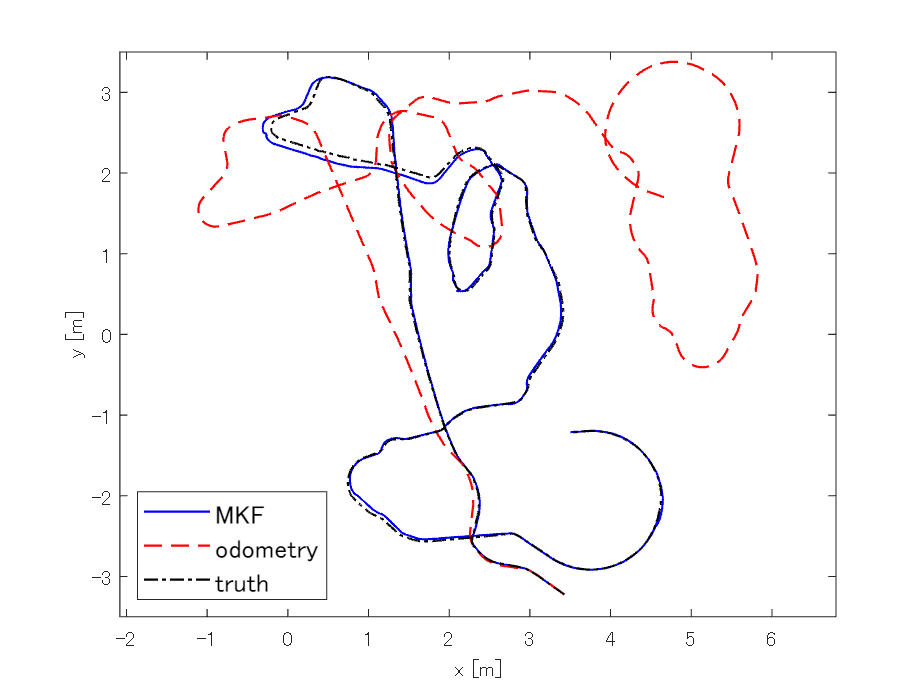

% 結果の表示
figure()
plot(result(:,1),result(:,2),'b-','LineWidth',1,'DisplayName','MKF')
hold on
plot(deadReconing(:,1),deadReconing(:,2),"r--",'LineWidth',1,'DisplayName','odometry')
plot(allData.trueX(1:steps),allData.trueY(1:steps),'k-.','LineWidth',1,'DisplayName','truth')
hold off
legend('FontSize',12,'Location','southwest')
xlabel('x [m]')
ylabel('y [m]')
ylim([-3.5,3.5])
axis('equal')